## Exercise #1

clear

format short
type ele1

function E1=ele1(n,r,i,j)
E1=eye(n);
E1(j,:) = E1(j,:) + E1(i,:).*r;
end


type ele2

function E2=ele2(n,i,j)
E2=eye(n);
E2([i j],:) = E2([j i],:);
end


type ele3

function E3=ele3(n,j,k)
E3=eye(n);
E3(j,:)=E3(j,:).*k;
end


Part 1

n=4; r=5; i=1; j=3; k=2

k = 2

(a)

I=eye(4)

I =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


E1=ele1(n,r,i,j)

E1 =      1     0     0     0
     0     1     0     0
     5     0     1     0
     0     0     0     1


% row 3 is replaced with (row 3) plus 5*(row 1)

E2=ele2(n,i,j)

E2 =      0     0     1     0
     0     1     0     0
     1     0     0     0
     0     0     0     1


% rows 1 and 3 are interchanged

E3=ele3(n,j,k)

E3 =      1     0     0     0
     0     1     0     0
     0     0     2     0
     0     0     0     1


% row 3 is scaled by k=2

(b)

detI=det(I)

detI = 1

detE1=det(E1)

detE1 = 1

% same as detI

detE2=det(E2)

detE2 = -1

% negative of detI

detE3=det(E3)

detE3 = 2

% 2 times detI (based on k, which is 2 here)

(c)

invE1=inv(E1)

invE1 =      1     0     0     0
     0     1     0     0
    -5     0     1     0
     0     0     0     1


% the 5 is now a -5

invE2=inv(E2)

invE2 =      0     0     1     0
     0     1     0     0
     1     0     0     0
     0     0     0     1


% same as E2

invE3=inv(E3)

invE3 =     1.0000         0         0         0
         0    1.0000         0         0
         0         0    0.5000         0
         0         0         0    1.0000


% the 2 is now a 0.5

(d)

M=[1 1 1 1; 2 2 2 2; 3 3 3 3; 4 4 4 4]

M =      1     1     1     1
     2     2     2     2
     3     3     3     3
     4     4     4     4


E1*M

ans =      1     1     1     1
     2     2     2     2
     8     8     8     8
     4     4     4     4


% row 3 replaced by (row 3) plus 5*(row 1)

E2*M

ans =      3     3     3     3
     2     2     2     2
     1     1     1     1
     4     4     4     4


% row 1 and 2 interchanged

E3*M

ans =      1     1     1     1
     2     2     2     2
     6     6     6     6
     4     4     4     4


% row 3 scaled by 2

Part 2

A=eye(6)

A =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


E1=ele1(6,3,2,5)

E1 =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     3     0     0     1     0
     0     0     0     0     0     1


E2=ele2(6,2,3)

E2 =      1     0     0     0     0     0
     0     0     1     0     0     0
     0     1     0     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


E3=ele3(6,4,5)

E3 =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     5     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


A=E3*E2*E1*A

A =      1     0     0     0     0     0
     0     0     1     0     0     0
     0     1     0     0     0     0
     0     0     0     5     0     0
     0     3     0     0     1     0
     0     0     0     0     0     1


% We know this matrix is invertible because it began as the identity square
% matrix. Only elementary row operations were performed on it, which are
% reversible. This means a reduced form of this matrix is the identity
% matrix that we started with. All identity matrices are linearly
% independent and invertible. Therefore, this matrix is invertible.

inv1=inv(A)

inv1 =     1.0000         0         0         0         0         0
         0         0    1.0000         0         0         0
         0    1.0000         0         0         0         0
         0         0         0    0.2000         0         0
         0         0   -3.0000         0    1.0000         0
         0         0         0         0         0    1.0000


inv2=inv(E1)*inv(E2)*inv(E3)

inv2 =     1.0000         0         0         0         0         0
         0         0    1.0000         0         0         0
         0    1.0000         0         0         0         0
         0         0         0    0.2000         0         0
         0         0   -3.0000         0    1.0000         0
         0         0         0         0         0    1.0000


if(isequal(inv1,inv2))
    disp("The inverses match.")
else
    disp("Check the code!")
end

The inverses match.


## Exercise #2

type rredef

function R = rredef(A)

[m,n] = size(A);


if (n >= m)
    for p = 1:n
        if any(A(:,p))
            index = p;
            [max_val, max_row] = max(abs(A(:,p)));
            A([1 max_row],:) = A([max_row 1],:);
            A(1,:) = A(1,:) ./ A(1,p);
            if (A(1,p) == -1)
                A(1,p) = A(1,p) * -1;
            end
            break
        end 
    end

    

    for j = 1:(n-1)
        for p = j:(m-1)
            A(p+1,:) = A(p+1,:) - ( A(j,:) .* A(p+1,index) );
        end
        A = closetozeroroundoff(A,7);
        if (index < m-1)
            index = index + 1;
        else  
            if (A(p+1,index+1) == 0)
                for v = (index+1):n
                    if (A(p+1,v) ~= 0)
                        A(p+1,:) = A(p+1,:) ./ A(p+1,v);
                    end
                end
                break
            else
                A(p+1,:) = A(p+1,:) ./ A(p+1,index+1);
                break
            end
        end

        for u=1:n
           

type closetozeroroundoff

function B=closetozeroroundoff(A,p)
A(abs(A)<10^-p)=0;
B=A;
end


%(a)
A=[2 1 1;1 2 3;1 1 1]

A =      2     1     1
     1     2     3
     1     1     1


R=rredef(A);

the reduced echelon form of A is


R =      1     0     0
     0     1     0
     0     0     1


%(b)
A=[zeros(3),randi(10,3,2)]

A =      0     0     0     5     5
     0     0     0     9    10
     0     0     0     2     8


R=rredef(A);

the reduced echelon form of A is


R =      0     0     0     1     0
     0     0     0     0     1
     0     0     0     0     0


%(c)
A=magic(4)

A =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


R=rredef(A);

the reduced echelon form of A is


R =     1.0000         0         0    1.0000
         0    1.0000         0    3.0000
         0         0    1.0000   -3.0000
         0         0         0         0


%(d)
A=magic(5)

A =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


R=rredef(A);

the reduced echelon form of A is


R =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


%(e)
A=ones(3)

A =      1     1     1
     1     1     1
     1     1     1


R=rredef(A);

the reduced echelon form of A is


R =      1     1     1
     0     0     0
     0     0     0


%(f)
A=rand(3,4)

A =     0.9595    0.8491    0.7577    0.6555
    0.6557    0.9340    0.7431    0.1712
    0.0357    0.6787    0.3922    0.7060


R=rredef(A);

the reduced echelon form of A is


R =     1.0000         0         0    6.9516
         0    1.0000         0   14.9291
         0         0    1.0000  -24.6672


%(g)
A=randi(10,5,3);A=[A,A(:,3)]

A =      1     7     4     4
     3     4     8     8
     1    10     8     8
     1     1     2     2
     9     5     5     5


R=rredef(A);

the reduced echelon form of A is


R =      1     0     0     0
     0     1     0     0
     0     0     1     1
     0     0     0     0
     0     0     0     0


## Exercise #3

format compact
type nonhomogen.m

function x=nonhomogen(A,b)
format
[~,n]=size(A);
fprintf('reduced echelon form of [A b] is ')
R=rref([A,b])
[nRow,nCol] = size(A);
if(rank(R) ~= rank(A))
    disp('The system is inconsistent')
elseif(nRow == nCol && det(A) ~= 0)
    disp('The system has a unique solution')
    A\b
else
    disp('There are infinitely many solutions')
    homobasis_b(A, b);
end
x=[];


type homobasis_b

function [C,p] = homobasis_b(A, b) 
format
[m,n]=size(A); 
red_ech_form=rats(rref(A));
num_rref_A = rref(A); 
C=[];
disp('the homogeneous system has non-trivial solutions') 
[~,pivot_c]=rref(A);
S=1:n;
nonpivot_c=setdiff(S,pivot_c);
q=numel(nonpivot_c);
j=1:q;
fprintf('a free variable is x%i\n',nonpivot_c(j)) 
C=zeros(n,q);
% Creating necessary intermediate variable 
identity_for_C = eye(size(nonpivot_c,2));
% Code to RECALCULATE C's rows
for i=1:numel(pivot_c)
    C(pivot_c(1,i),:)=num_rref_A(i,nonpivot_c)*-1; 
end
for i=1:size(nonpivot_c,2)
    C(nonpivot_c(1,i),:)= identity_for_C(i,:); 
end
fprintf('a basis for the solution set of the homogeneous system\n')
fprintf('is formed by the columns of the matrix')
C


%(a)
A=[1 -2 3], b=randi(10,1,1)

A =      1    -2     3


b = 5

x=nonhomogen(A,b);

reduced echelon form of [A b] is 

R =      1    -2     3     5


There are infinitely many solutions
the homogeneous system has non-trivial solutions
a free variable is x2
a free variable is x3
a basis for the solution set of the homogeneous system
is formed by the columns of the matrix

C =      2    -3
     1     0
     0     1


%(b)
A=magic(3), b=randi(10,3,1)

A =      8     1     6
     3     5     7
     4     9     2


b =      7
     8
     8


x=nonhomogen(A,b);

reduced echelon form of [A b] is 

R =     1.0000         0         0    0.3861
         0    1.0000         0    0.5944
         0         0    1.0000    0.5528


The system has a unique solution


ans =     0.3861
    0.5944
    0.5528


%(c)
A=magic(4), b=randi(10,4,1)

A =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


b =      3
     7
     7
     2


x=nonhomogen(A,b);

reduced echelon form of [A b] is 

R =      1     0     0     1     0
     0     1     0     3     0
     0     0     1    -3     0
     0     0     0     0     1


The system is inconsistent


%(d)
B=[0 1 2 3;0 2 4 6]; A=[B; eye(4)], b=sum(A,2)

A =      0     1     2     3
     0     2     4     6
     1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


b =      6
    12
     1
     1
     1
     1


x=nonhomogen(A,b);

reduced echelon form of [A b] is 

R =      1     0     0     0     1
     0     1     0     0     1
     0     0     1     0     1
     0     0     0     1     1
     0     0     0     0     0
     0     0     0     0     0


There are infinitely many solutions
the homogeneous system has non-trivial solutions
a free variable is x
a basis for the solution set of the homogeneous system
is formed by the columns of the matrix
C =

  4×0 empty double matrix



%(e)
A=[0 1 0 2 0 3; 0 2 0 4 0 6; 0 4 0 8 0 6], b=ones(3,1)

A =      0     1     0     2     0     3
     0     2     0     4     0     6
     0     4     0     8     0     6


b =      1
     1
     1


x=nonhomogen(A,b);

reduced echelon form of [A b] is 

R =      0     1     0     2     0     0     0
     0     0     0     0     0     1     0
     0     0     0     0     0     0     1


The system is inconsistent


%(f)
A=[0 1 0 2 0 3; 0 2 0 4 0 6; 0 4 0 8 0 6], b=sum(A,2)

A =      0     1     0     2     0     3
     0     2     0     4     0     6
     0     4     0     8     0     6


b =      6
    12
    18


x=nonhomogen(A,b);

reduced echelon form of [A b] is 

R = 3×7
     0     1     0     2     0     0     3
     0     0     0     0     0     1     1
     0     0     0     0     0     0     0


There are infinitely many solutions
the homogeneous system has non-trivial solutions
a free variable is x1
a free variable is x3
a free variable is x4
a free variable is x5
a basis for the solution set of the homogeneous system
is formed by the columns of the matrix

C = 6×4
     1     0     0     0
     0     0    -2     0
     0     1     0     0
     0     0     1     0
     0     0     0     1
     0     0     0     0


%(g)
A=[0 0 1 2 3;0 0 2 4 5], b=A(:,end)

A = 2×5
     0     0     1     2     3
     0     0     2     4     5


b = 2×1
     3
     5


x=nonhomogen(A,b);

reduced echelon form of [A b] is 

R = 2×6
     0     0     1     2     0     0
     0     0     0     0     1     1


There are infinitely many solutions
the homogeneous system has non-trivial solutions
a free variable is x1
a free variable is x2
a free variable is x4
a basis for the solution set of the homogeneous system
is formed by the columns of the matrix

C = 5×3
     1     0     0
     0     1     0
     0     0    -2
     0     0     1
     0     0     0


%(h)
A=[0 0 1 2 3;0 0 2 4 6], b=A(:,end)

A = 2×5
     0     0     1     2     3
     0     0     2     4     6


b = 2×1
     3
     6


x=nonhomogen(A,b);

reduced echelon form of [A b] is 

R = 2×6
     0     0     1     2     3     3
     0     0     0     0     0     0


There are infinitely many solutions
the homogeneous system has non-trivial solutions
a free variable is x1
a free variable is x2
a free variable is x4
a free variable is x5
a basis for the solution set of the homogeneous system
is formed by the columns of the matrix

C = 5×4
     1     0     0     0
     0     1     0     0
     0     0    -2    -3
     0     0     1     0
     0     0     0     1


## Exercise #4

type areavol

function D=areavol(A)
format
D=0;

%find (rows x col) = (m,n)
[m,n]=size(A);

%parallelogram (2x2)
if m == 2 && n==2
    %check if linearly independent
    if rank(A) == 2
        %Area = b*h
        D = A(1,1) * A(2,2);
        fprintf('The area of the parallelogram is\n')
        D    
    else
        fprintf('The parallelogram cannot be built')
    end
    
%parallelepiped (3x3)    
else
    %check if linearly independent
    if rank(A) == 3
        %Area = b*h*w
        D = A(1,1) * A(2,2) * A(3,3);
        fprintf('The area of the parallelepiped is\n')
        D    
    else
        fprintf('The parallelepiped cannot be built')
    end
end

end




%(a)
A=eye(2)

A = 2×2
     1     0
     0     1


D=areavol(A);

The area of the parallelogram is


D = 1

%(b)
A=magic(3)

A = 3×3
     8     1     6
     3     5     7
     4     9     2


D=areavol(A);

The area of the parallelepiped is


D = 80

%(c)
A=randi(10,2)

A = 2×2
     2    10
     5     4


D=areavol(A);

The area of the parallelogram is


D = 8

%(d)
A=fix(10*rand(3))

A = 3×3
     5     2     8
     2     5     9
     7     6     5


D=areavol(A);

The area of the parallelepiped is


D = 125

%(e)
B=randi([-10,10],2,1); 
A = [B,3*B]

A = 2×2
    -8   -24
    -7   -21


D=areavol(A);

The parallelogram cannot be built

%(f)
X=randi([-10,10],3,1);
Y=randi([-10,10],3,1);
A=[X,Y,X+Y] 

A = 3×3
    -5     7     2
     7    -5     2
    -5     9     4


D=areavol(A);

The parallelepiped cannot be built

## Exercise #5

RX (reflection across the x1 -axis)

clear
RX = [1 0; 0 -1]

RX = 2×2
     1     0
     0    -1


RY (reflection across the x2 -axis)

RY = [-1 0; 0 1]

RY = 2×2
    -1     0
     0     1


VS (vertical shear with k = 3 )

VS = [1 0; 3 1]

VS = 2×2
     1     0
     3     1


RS (reflection across the line x2 = x1 )

RS = [0 1; 1 0]

RS = 2×2
     0     1
     1     0


RA (reflection across the line x2 = −x1 )

RA = [0 1; -1 0]

RA = 2×2
     0     1
    -1     0


type transf

function C=transf(A,E)
C=A*E;
x=C(1,:);y=C(2,:);
plot(x,y)
v=[-5 5 -5 5];
axis(v)
end


This function recieves parameters A and E and first multiplies them together to get C. It then creates 2 sub matrices x and y from C representing the coordinate plane. Then it uses the plot command to display them on the matlab plot. It then draw the x and y axis from -5 to 5.

E=[0 1 1 0 0;0 0 1 1 0]; A=eye(2);
hold on

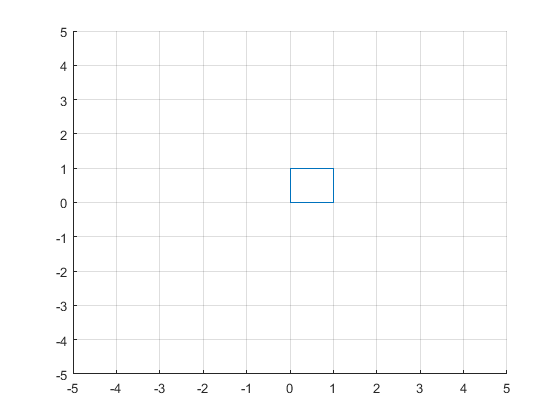

grid on
E=transf(A,E);

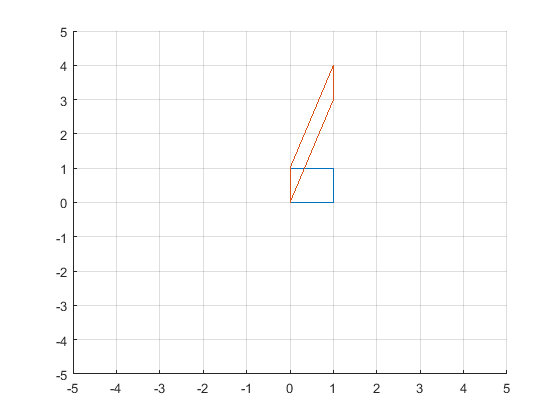

A = VS;
E=transf(A,E);

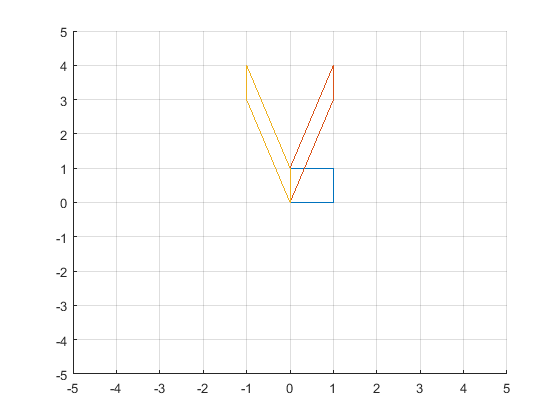

A = RY;
E=transf(A,E);

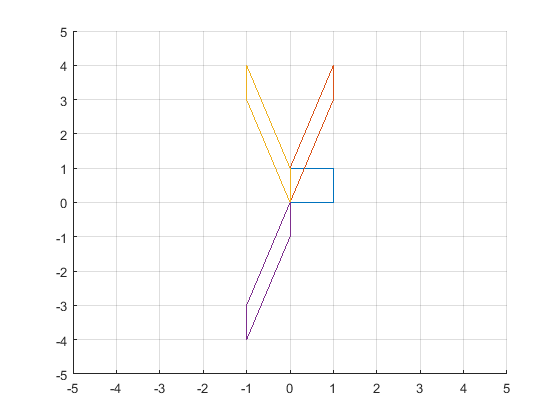

A = RX;
E=transf(A,E);

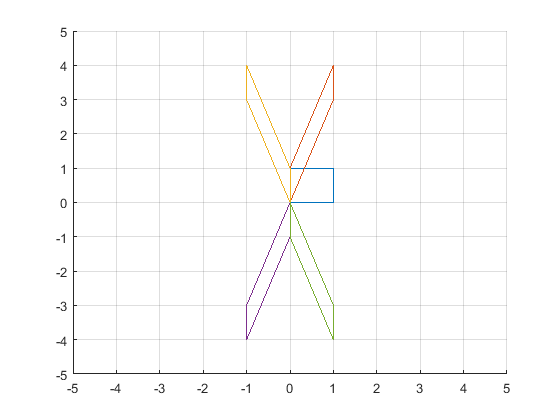

A = RY;
E=transf(A,E);

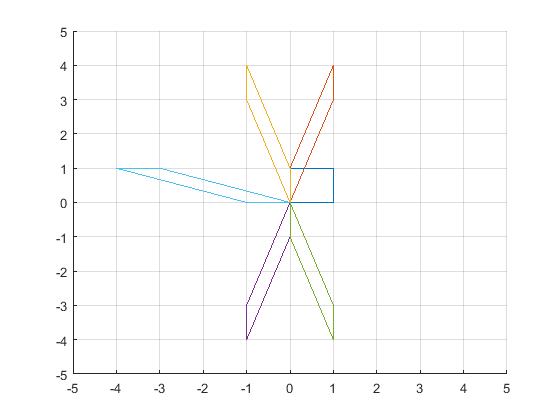

A = RS;
E=transf(A,E);

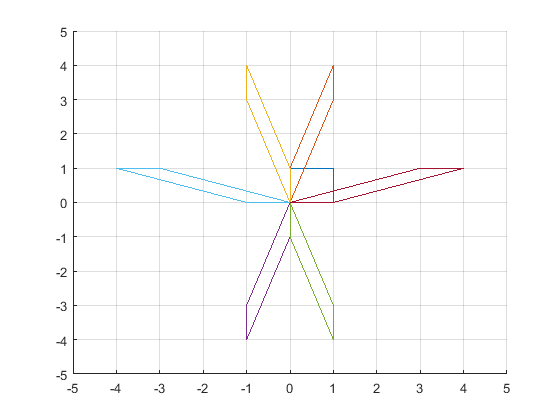

A = RY;
E=transf(A,E);

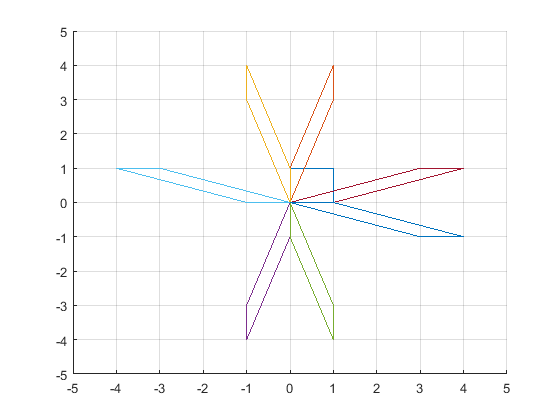

A = RX;
E=transf(A,E);

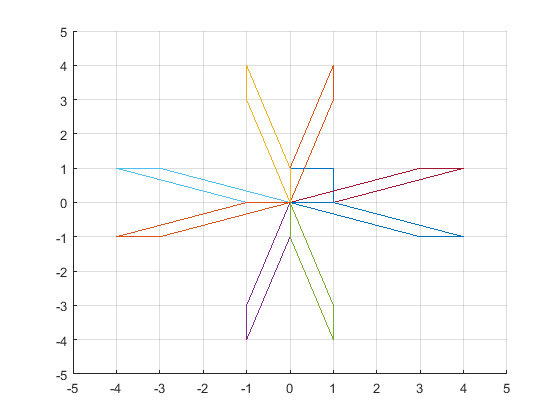

E = 2×5
     0    -3    -4    -1     0
     0    -1    -1     0     0


A = RY;
E=transf(A,E)

## Exercise #6

## Exercise #7

type production

function x = production(C,d)
n=size(C,2);
x=[];

%check if inputs are valid
%check if C has all nonnegative entries
if all(C >= 0)
    %valid
else
    disp('Consumption matrix contains negative values')
    return
end
%check if d has all nonnegative entries
if all(d >= 0)
    %valid
else
    disp('Final demand vector d contains negative values')
    return
end
%check if C's column sums are all less than 1
if all(sum(C) < 1)
    %valid
else
    disp('Each column sum of C should be less than 1')
    return
end

%should be valid inputs
I = eye(n);

%Aaug = [A d]
x = (I-C)\d;
if all(x > 0)
    disp('the unique production vector is')
    x
else
    disp('check the code!')
end

x0=d;
x1=x0;
k=0;
%closetozeroroundoff(x-x1, 1)
while all(closetozeroroundoff(x-x1, 1) ~= 0)
    k = k + 1;
    I = I + C^k;
    x1=inv(I)\d;
end

disp('the production vector calculated by recurrence relation is')
x1
fprintf('the number of iteration to match the output x is %i\n',k)

end



%(a)
C = [.5 .4 .2; .2 .3 .1; .1 .1 .3]

C = 3×3
    0.5000    0.4000    0.2000
    0.2000    0.3000    0.1000
    0.1000    0.1000    0.3000


d = [50; 30; 20]

d = 3×1
    50
    30
    20


x = production(C, d);

the unique production vector is


x = 3×1
  225.9259
  118.5185
   77.7778


the production vector calculated by recurrence relation is


x1 = 3×1
  225.6447
  118.3779
   77.6870


the number of iteration to match the output x is 24



%(b)
C = importdata('consumption.csv')

Error using importdata (line 139)
Unable to open file.

d = importdata('demand.csv')
x = production(C,d);

% Questions 
% 1. (3, 4) of C represents inputs consumed per unit of output by basic
% nonmetal products and agriculture that were purchased from basic metal
% products and mining
% 2. Sector 7 needs to produce 13,830 units
%(c)
C = importdata('consumption.csv')
d = importdata('demand_1.csv')
x = production(C,d);
%(d)
C = importdata('consumption_1.csv')
d = importdata('demand_1.csv')
x = production(C,d);
%(e)
C = importdata('consumption_1.csv')
d = importdata('demand_2.csv')
x = production(C,d);
